https://www.mathworks.com/help/symbolic/solve-differential-equation-numerically-1.html

syms y(t)
[V] = odeToVectorField(diff(y, 2) == (1 - y^2)*diff(y) - y)

$$V = \left(\begin{array}{c} Y_{2}\\ -\left({Y_{1}}^{2}-1\right)\,Y_{2}-Y_{1} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-(Y(1).^2-1.0).*Y(2)-Y(1)]


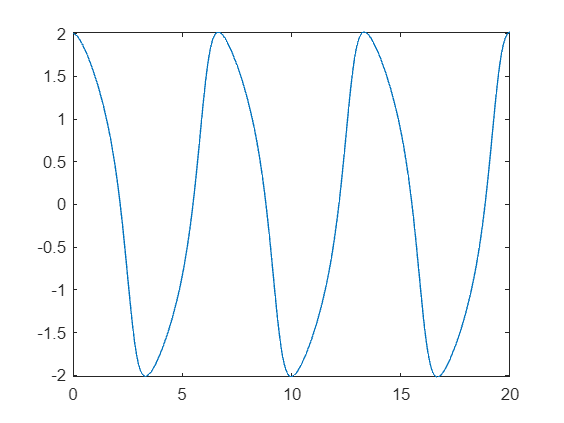

sol = ode45(M,[0 20],[2 0]);
fplot(@(x)deval(sol,x,1), [0, 20])

applying classic spring damper model

syms y(t)
%constants
k = 1; %spring
c = 1; %damper
m = 1; %mass
[V] = odeToVectorField(-m*diff(y, 2) == c*diff(y) + k*y)

$$V = \left(\begin{array}{c} Y_{2}\\ -Y_{1}-Y_{2} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-Y(1)-Y(2)]


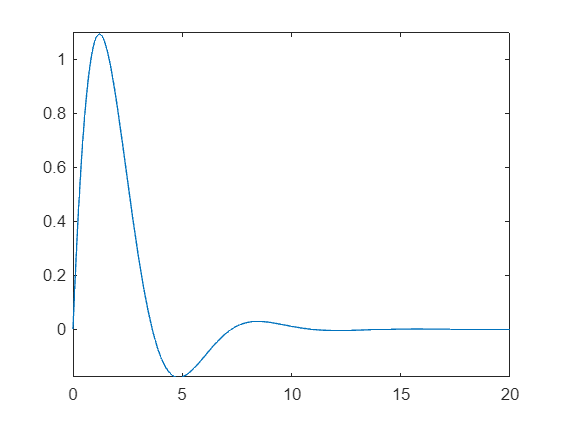

sol = ode45(M,[0 20],[0 2]);
fplot(@(x)deval(sol,x,1), [0, 20])

confirm by solving mathematically by hand

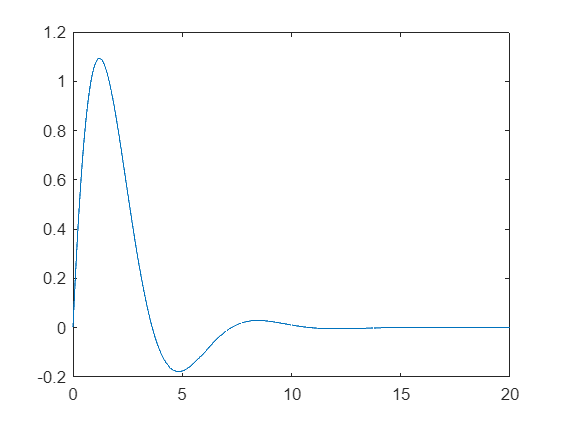

x = linspace(0,20,10000);
y = (4/sqrt(3))*exp(-1/2.*x).*sin(x.*sqrt(3)/2);
plot(x,y)

2 DOF spring sys (https://www.mathworks.com/help/symbolic/solve-a-system-of-differential-equations.html#SolveASystemOfDifferentialEquationsExample-2)

m = 1;
k = 2; %why are these not used????
syms x(t) y(t)
A = [-4 2; 2 -2];
Y = [x; y];
odes = diff(Y,2) == A*Y

$$odes(t) = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=2\,y\left(t\right)-4\,x\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=2\,x\left(t\right)-2\,y\left(t\right) \end{array}\right)$$

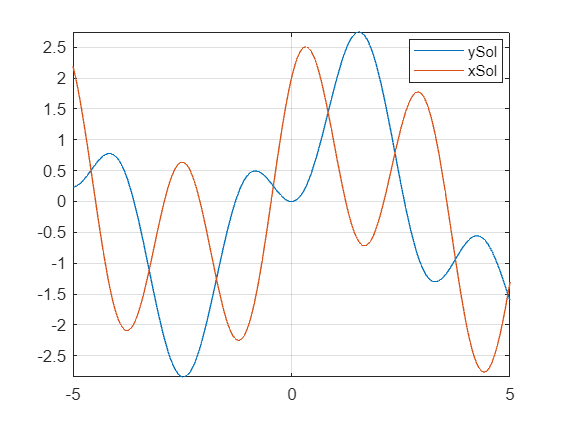

D = diff(Y);
C = [Y(0) == [2;0;],D(0) == [3;0]];
[xSol(t),ySol(t)] = dsolve(odes,C);
xSol(t) = simplify(xSol(t));
ySol(t) = simplify(ySol(t));
clf
fplot(ySol)
hold on
fplot(xSol)
grid on
legend('ySol','xSol','Location','best')

confirm by graphing system of first order ODEs 

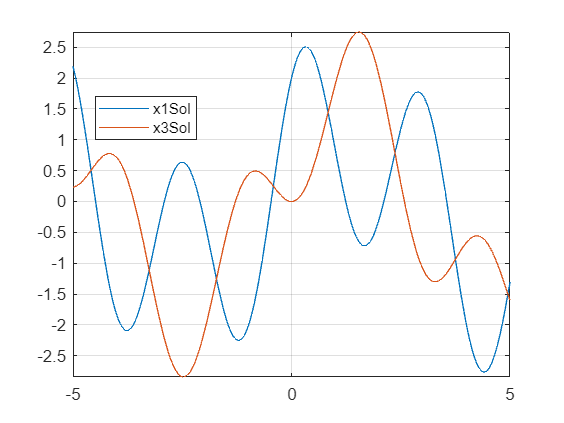

syms x1(t) x2(t) x3(t) x4(t)
A = [0 1 0 0; -4 0 2 0; 0 0 0 1; 2 0 -2 0];
Y = [x1; x2; x3; x4];
odes = diff(Y) == A*Y;
C = [Y(0) == [2;3;0;0;]];
[x1Sol(t),x2Sol(t),x3Sol(t),x4Sol(t)] = dsolve(odes,C);
x1Sol(t) = simplify(x1Sol(t));
x3Sol(t) = simplify(x3Sol(t));
clf
fplot(x1Sol)
hold on
fplot(x3Sol)
grid on
legend('x1Sol','x3Sol','Location','best')

2dof mass spring damper system (solved numerically) assum. identical mass and constants

clf
hold on
m = 1;
k = 1; 
c = 1;
syms x(t) y(t)
A = [-(2*k/m) k/m; k/m -k/m];
B = [-2*c/m c/m; c/m -c/m];
Y = [x; y];
[V] = odeToVectorField(diff(Y,2) == A*Y + B*diff(Y))

$$V = \left(\begin{array}{c} Y_{2}\\ Y_{3}-Y_{2}-Y_{1}+Y_{4}\\ Y_{4}\\ Y_{1}+Y_{2}-2\,Y_{3}-2\,Y_{4} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-Y(1)-Y(2)+Y(3)+Y(4);Y(4);Y(1)+Y(2)-Y(3).*2.0-Y(4).*2.0]



timeSpan = [0 20]; % Interval
stepSize = 0.01; % Smaller step size for more time points
timeGrid = timeSpan(1):stepSize:timeSpan(2); % Create a finer time grid

%sol = ode45(M,[0 20],[1 0 0 0])
sol = ode45(M,timeGrid,[1 0 0 0])

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 2.0095e-04 0.0012 0.0062 0.0313 0.1569 0.4002 0.7364 1.1406 1.5989 2.0181 2.4744 3.0198 3.6549 4.4601 5.4083 6.3367 7.3699 8.6846 9.9262 11.2226 12.4297 13.7624 15.0322 16.3460 17.5806 18.9234 20]
          y: [4×28 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


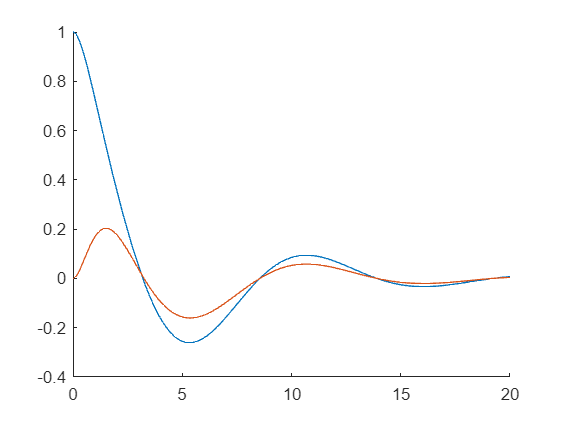


fplot(@(x)deval(sol,x,1), [0, 20])
fplot(@(x)deval(sol,x,3), [0, 20])


% Extract time points and solution values
timePoints = sol.x;
solutionValues = deval(sol, timePoints, 1:4) % Assuming the solution has 4 components

solutionValues =     1.0000    1.0000    1.0000    1.0000    0.9995    0.9889    0.9383    0.8305    0.6781    0.5030    0.3516    0.2009    0.0437   -0.1018   -0.2194   -0.2607   -0.2186   -0.1192    0.0113    0.0826    0.0892    0.0538    0.0043   -0.0267   -0.0332   -0.0219   -0.0038    0.0072
         0   -0.0002   -0.0012   -0.0062   -0.0304   -0.1342   -0.2689   -0.3584   -0.3861   -0.3735   -0.3474   -0.3123   -0.2625   -0.1939   -0.0977    0.0068    0.0772    0.1068    0.0827    0.0307   -0.0170   -0.0374   -0.0330   -0.0148    0.0038    0.0129    0.0126    0.0075
         0    0.0000    0.0000    0.0000    0.0005    0.0105    0.0529    0.1239    0.1852    0.2023    0.1754    0.1176    0.0341   -0.0557   -0.1326   -0.1607   -0.1352   -0.0737    0.0070    0.0510    0.0551    0.0332    0.0027   -0.0165   -0.0205   -0.0136   -0.0024    0.0044
         0    0.0002    0.0012    0.0062    0.0299    0.1231    0.2081    0.1967    0.0994   -0.0213   -0.1008   -0.1457   -0.1536   -0.1245


% Prepare data for export
data = [timePoints', solutionValues(1,:)', solutionValues(3,:)']; % Columns for t, x, y

% Export to CSV
filename = 'solution_data_damping.csv';
writematrix(data, filename);

% Display message
disp(['Data exported to ', filename]);

Data exported to solution_data_damping.csv


manual simplify to first order (keep in mind that the entries switched order in symbolic vector V)

syms x1(t) x2(t) x3(t) x4(t)
A = [0 1 0 0; -2*k/m -c*2/m k/m c/m; 0 0 0 1; k/m c/m -k/m -c/m];
Y = [x1; x2; x3; x4];
clf
hold on
[V] = odeToVectorField(diff(Y) == A*Y )

$$V = \left(\begin{array}{c} Y_{3}-2\,Y_{2}-2\,Y_{1}+Y_{4}\\ Y_{1}\\ Y_{4}\\ Y_{1}+Y_{2}-Y_{3}-Y_{4} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(1).*-2.0-Y(2).*2.0+Y(3)+Y(4);Y(1);Y(4);Y(1)+Y(2)-Y(3)-Y(4)]


sol = ode45(M,[0 20],[0 1 0 0])

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 1.0048e-04 6.0285e-04 0.0031 0.0157 0.0785 0.2658 0.5593 0.9321 1.3646 1.8150 2.2155 2.7186 3.2836 3.9128 4.6715 5.4727 6.1528 7.0003 8.2402 9.4682 10.7197 11.9678 13.3229 14.6178 15.7936 17.0683 18.4064 19.7140 20]
          y: [4×30 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


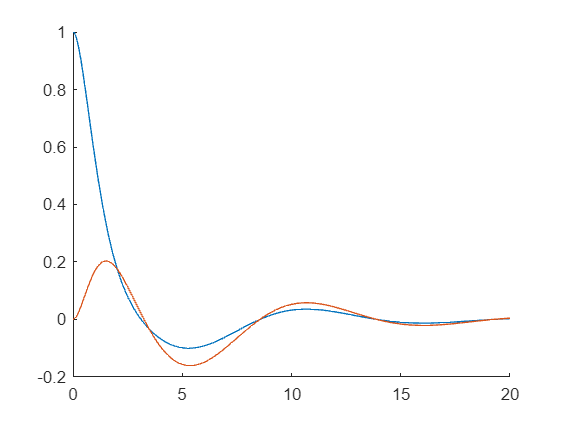

fplot(@(x)deval(sol,x,2), [0, 20])
fplot(@(x)deval(sol,x,3), [0, 20])